MATLAB技巧——histogram绘图命令，搭配的mlx文件

clc;clear;close all;

## ✅ 基础用法（经典示例）

###  示例 1：绘制基本直方图

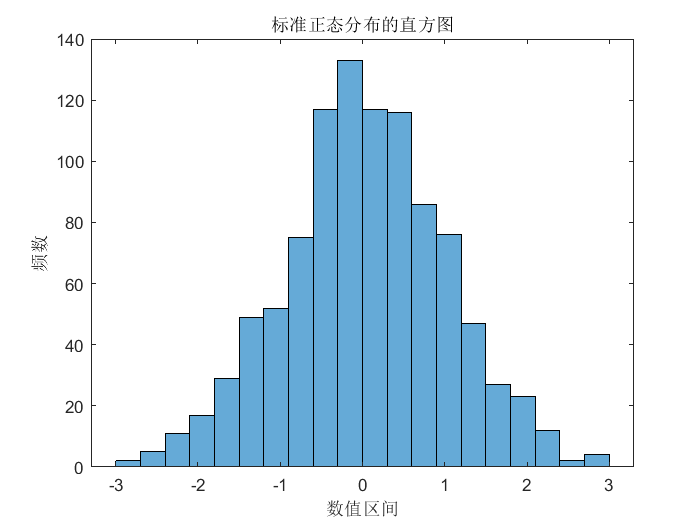

figure;
data = randn(1000, 1);  % 生成正态分布数据
histogram(data);
title('标准正态分布的直方图');
xlabel('数值区间');
ylabel('频数');

### 示例 2：指定柱子个数（bins）

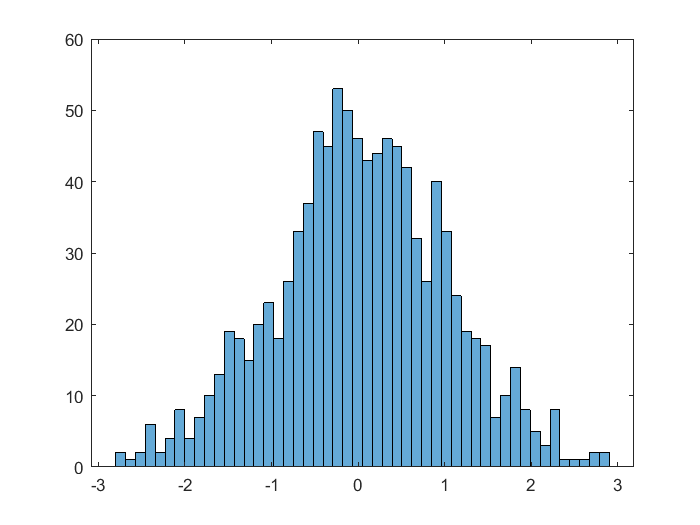

figure;
histogram(data, 50);  % 强制使用50个柱子

### 示例 3：设置柱子的边界（edges）

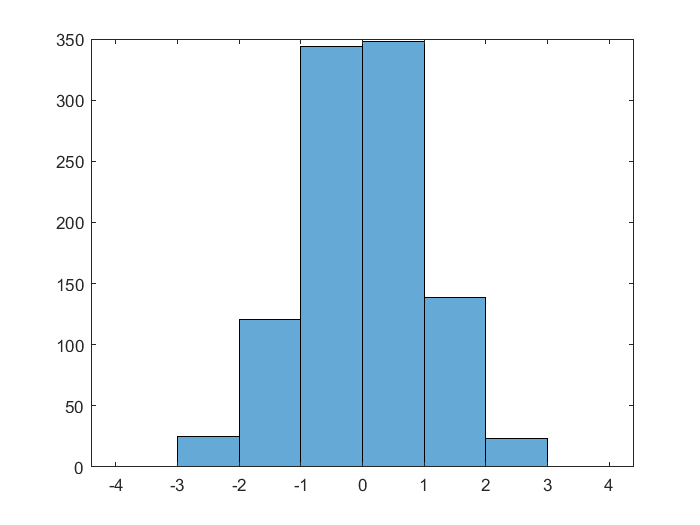

figure;
edges = -4:1:4;  % 每隔1一个区间
histogram(data, edges);

### 示例4：设置坐标轴和标题

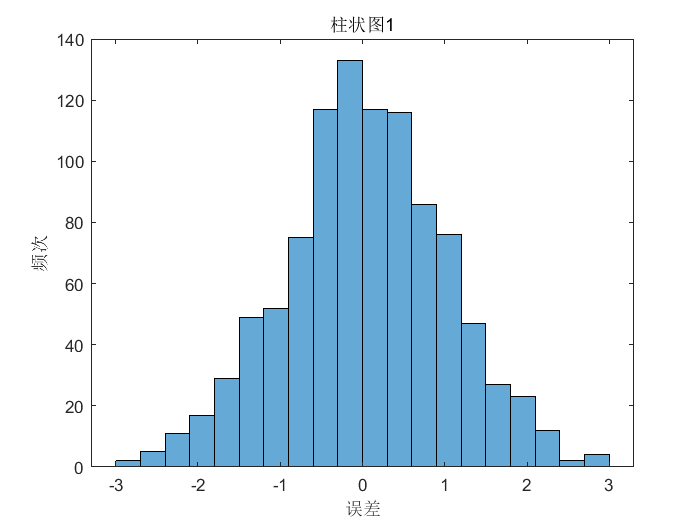

figure;
histogram(data);
xlabel('误差');
ylabel('频次');
title('柱状图1')

## ✅ 进阶用法

### 🎯 示例5：归一化为概率密度（概率密度图）

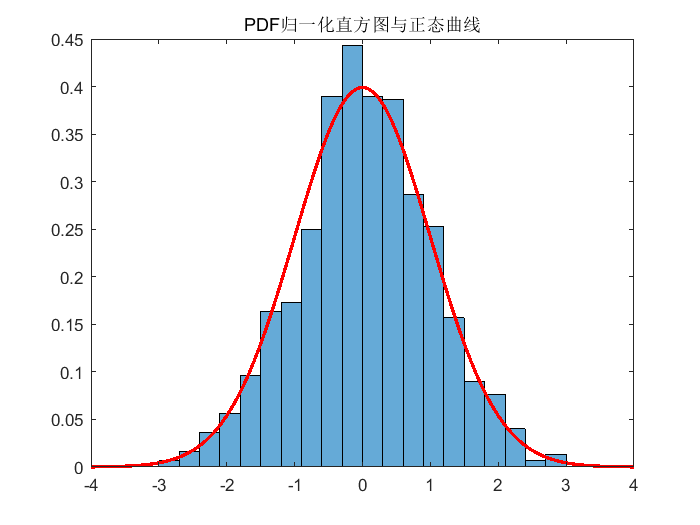

figure;
histogram(data, 'Normalization', 'pdf');  % 概率密度
hold on;
x = -4:0.01:4;
plot(x, normpdf(x, 0, 1), 'r', 'LineWidth', 2);  % 正态分布函数曲线
title('PDF归一化直方图与正态曲线');

> `'pdf'` 会使面积为 1，常用于分布拟合。

### 示例6：绘制多组数据直方图对比

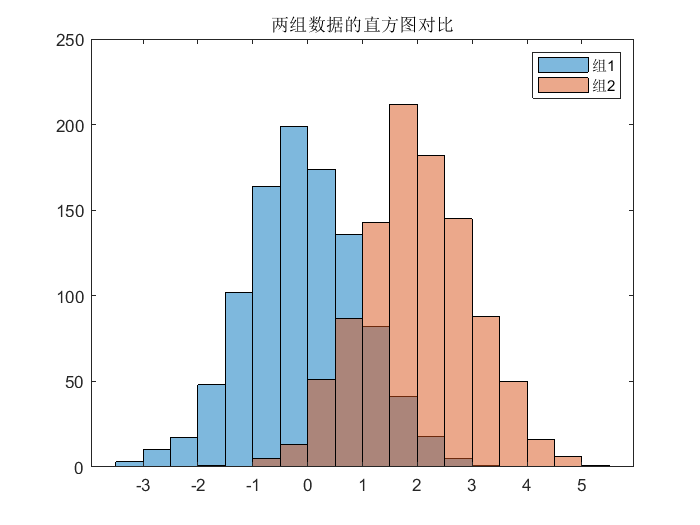

figure;
data1 = randn(1000,1);
data2 = 2 + randn(1000,1);

histogram(data1, 'BinWidth', 0.5, 'FaceAlpha', 0.5);  % 半透明
hold on;
histogram(data2, 'BinWidth', 0.5, 'FaceAlpha', 0.5);
legend('组1', '组2');
title('两组数据的直方图对比');

### 示例7：水平显示直方图（转换方向）

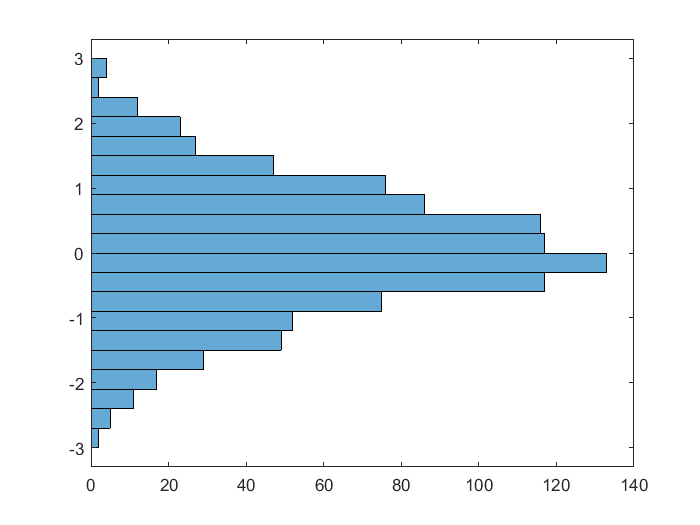

figure;
histogram(data, 'Orientation', 'horizontal');

### 示例 8：设置颜色、边框、透明度

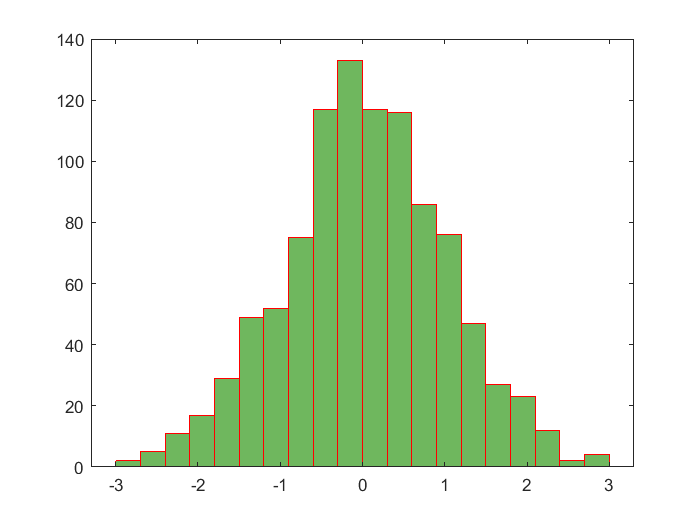

figure;
h = histogram(data);
h.FaceColor = [0.2 0.6 0.1];     % 柱子填充颜色
h.EdgeColor = 'r';               % 红色边框
h.FaceAlpha = 0.7;               % 透明度

### 示例 9：获取直方图数据用于分析

% h = histogram(data);
counts = h.Values;     % 每个柱子的数量
edges = h.BinEdges;    % 每个柱子的边界
fprintf('各个柱子的数量:%s',num2str(counts));

各个柱子的数量:2    5   11   17   29   49   52   75  117  133  117  116   86   76   47   27   23   12    2    4

fprintf('各个柱子的边界:%s',num2str(edges));

各个柱子的边界:-3        -2.7        -2.4        -2.1        -1.8        -1.5        -1.2        -0.9        -0.6        -0.3           0         0.3         0.6         0.9         1.2         1.5         1.8         2.1         2.4         2.7           3

## ✅ 综合使用方法

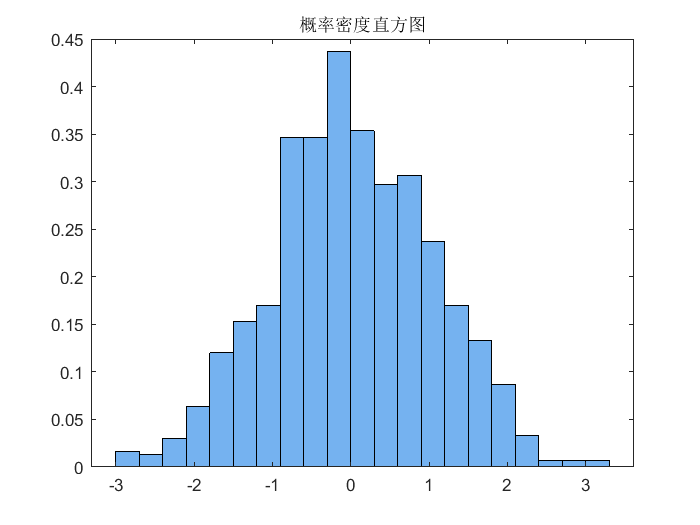

figure;
data = randn(1000,1);
histogram(data, 'Normalization', 'pdf', ...
          'BinWidth', 0.3, ...
          'FaceColor', [0.1 0.5 0.9], ...
          'EdgeColor', 'k', ...
          'FaceAlpha', 0.6);
title('概率密度直方图');